## PART 1: KINEMATICS

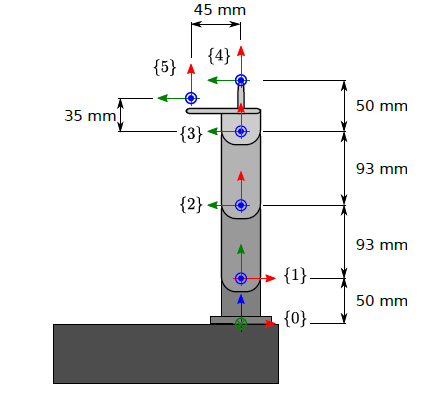

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations
c90 = 0;
s90 = 1;
L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;
% % Uncomment for symbolic representation
syms c1 s1 c2 s2 c3 s3 c4 s4 c5 s5 c90 s90 L01 L12 L23 L34 L45 L35

% {0} -> {1}
T01 = [1 0 0 0;
       0 c1 -s1 0;
       0 s1 c1 L01;
       0 0 0 1];
% {1} -> {2}
T12 = [c2 -s2 0 L12;
       s2 c2 0 0;
       0 0 1 0;
       0 0 0 1];
% {2} -> {3}
T23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {4}
T34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
% {3} -> {5}
T35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \left(\begin{array}{cccc} c_{2} & -s_{2} & 0 & L_{12}+L_{23}\,c_{2}+L_{34}\,c_{2}\\ c_{1}\,s_{2} & c_{1}\,c_{2} & -s_{1} & L_{23}\,c_{1}\,s_{2}+L_{34}\,c_{1}\,s_{2}\\ s_{1}\,s_{2} & c_{2}\,s_{1} & c_{1} & L_{01}+L_{23}\,s_{1}\,s_{2}+L_{34}\,s_{1}\,s_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \left(\begin{array}{cccc} c_{2} & -s_{2} & 0 & L_{12}+L_{23}\,c_{2}+L_{35}\,c_{2}-L_{45}\,s_{2}\\ c_{1}\,s_{2} & c_{1}\,c_{2} & -s_{1} & L_{45}\,c_{1}\,c_{2}+L_{23}\,c_{1}\,s_{2}+L_{35}\,c_{1}\,s_{2}\\ s_{1}\,s_{2} & c_{2}\,s_{1} & c_{1} & L_{01}+L_{45}\,c_{2}\,s_{1}+L_{23}\,s_{1}\,s_{2}+L_{35}\,s_{1}\,s_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.